clear
Freqs = CleanDir('C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\TRawFreq');

Behaviors = CleanDir('C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\StableDoubleNegQ');

Deci.Analysis.Freq.Extra.Corr.Behavior = {'StableDoubleNegQ\mEV' 'StableDoubleNegQ\mPE' 'StableDoubleNegQ\mR' 'StableDoubleNegQ\mEV_other'...
                                          'StableDoubleNegQ\sEV' 'StableDoubleNegQ\sPE' 'StableDoubleNegQ\sR' 'StableDoubleNegQ\sEV_other'};
Deci.Analysis.Freq.Extra.Corr.categorical = [5:8];
Deci.Analysis.Freq.Extra.Corr.signed = [5:8];



states = [20 21 23 24 120 121];

for subj = 1:length(Freqs)

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\TRawFreq\' Freqs{subj} '\Fdb Onset\All\FCz.mat']);

    data{subj} = cat(1,time_rawfreq.trialpow{:});
    time = time_rawfreq.time;

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\TRawFreq\' Freqs{subj} '\Stim Onset\All\FCz.mat']);

    bsl{subj} = cat(1,time_rawfreq.trialpow{:});
    bsltime = time_rawfreq.time;

    bsl{subj} = repmat(nanmean(nanmean(bsl{subj}(:,:,:,bsltime >= -.2 & bsltime <= 0),4),1),[size(data{subj},1) 1 1 size(data{subj},4)]);

    data{subj} = [data{subj} - bsl{subj}]./bsl{subj};
    %data{subj} = [data{subj} - bsl{subj}]; 

    b = load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\StableDoubleNegQ\S\' filesep Freqs{subj} '\All.mat']);


    for behv = 1:length(Deci.Analysis.Freq.Extra.Corr.Behavior)

        load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\' Deci.Analysis.Freq.Extra.Corr.Behavior{behv} filesep Freqs{subj} '\All.mat']);

        bparam{behv} = cat(2,param{:})';
        bparam{behv} = bparam{behv}(time_rawfreq.trials);
        if ismember(behv,Deci.Analysis.Freq.Extra.Corr.signed)
        bparam{behv}(bparam{behv} == 0) = 1;
        bparam{behv}(bparam{behv} == -1) = 2;
        end

        for stat = 1:length(states)

            blk = 1;
            for block = 1:length(b.param)

               

                if ismember(states(stat),b.param{block})
                   pos = ismember(b.param{block},states(stat));

                   blkparam{behv}(stat,subj,blk,:) = nan([40 1]);

                   blkparam{behv}(stat,subj,blk,:) = [param{block}(pos) nan([1 40-length(param{block}(pos))])];

                   blk = blk + 1;
                else
                    continue
                end

            end
            
        end


    end

    behav{subj} = cat(2,bparam{:});

end

brain = cat(1,data{:});
behavior = cat(1,behav{:});



BehvTitles = {'mEV' 'mPe' 'mR', 'mEV_other' ...
             'sEV' 'sPe' 'sR','sEV_other','brain'};

%Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1  + mPe*sPe  + mR*sR';

Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1 + mEV*sEV + mR + sR +  mPe*sPe +  mEV_other*sEV_other';

for time = 1:size(brain,4)

    BBCorr = array2table([behavior brain(:,:,:,time)],'VariableNames',BehvTitles);

    mdl = fitlm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',BehvTitles(5:8));

    statistics(1,time) = table2array(mdl.Coefficients(1,1));

    a =anova(mdl,'summary');
    
    observerstat(time) =  table2array(a(2,4));

    for coef = 2:length(table2array(mdl.Coefficients(:,4)))

        statistics(coef,time) = 0;

        if table2array(a(2,5)) <.05
            coefs = table2array(mdl.Coefficients(:,4));

            if table2array(mdl.Coefficients(coef,4)) < .05

                statistics(coef,time) = table2array(mdl.Coefficients(coef,1));
            end
        end
    end

end


cfg.alpha = .05

cfg = struct with fields:
    alpha: 0.0500


s.dfnum = table2array(a(2,2))

s = struct with fields:
    dfnum: 11


s.dfdenom = mdl.NumObservations - s.dfnum;
s.critval = finv(1-cfg.alpha,s.dfnum,s.dfdenom);

design = [];
numofrands = 500;


Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1 + mEV + sEV + mR*sR +  mPe*sPe ';

randstat = zeros(numofrands,size(brain,4));
sizebraine = size(brain,4);
parfor shuf = 1:numofrands
    display(shuf);
for time = 1:sizebraine

    BBCorr = array2table([behavior brain(randperm(length(brain)),:,:,time)],'VariableNames',BehvTitles);
    mdl = fitlm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',BehvTitles(5:8));
    a =anova(mdl,'summary');
    randstat(shuf,time) =  table2array(a(2,4));

end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 36).
     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    78

    84

    90

    96

   108

   156

    54

    60

   114

   132

   138

    48

    72

   102

   150

   162

   180

   246

    66

   120

   144

   210

    42

   168

   174

   186

   192

   204

   216

   240

   126

   222

   228

   234

   198

   252

    89

    47

    65

   131

   137

   155

    59

    71

    83

    95

   107

   119

   185

    53

    77

   101

   113

   149

   167

   191

   209

   221

   227

   233

    41

   125

   143

   161

   173

   179

   203

   215

   239

   245

   251

   197

    88

   130

 


for eachstat = 1:size(observerstat,1)

    tempcfg.clustercritval = s.critval;
    tempstatobs = observerstat(eachstat,:);
    tempstatrand = randstat(:,:,eachstat);
    tempcfg.tail = 1;
    tempcfg.clustertail = 1;
    tempcfg.clusterthreshold = 'nonparametric_common';
    tempcfg.dim = [1 size(observerstat,2)]
    tempcfg.feedback = 'none';
    tempcfg.clusterstatistic = 'maxsum';
    tempcfg.numrandomization = 500;
    tempcfg.clusteralpha = .001;

    [tempstat{eachstat}, cfg] = clusterstat(tempcfg, tempstatrand', tempstatobs);
end

tempcfg = struct with fields:
      clustercritval: 1.7893
                tail: 1
         clustertail: 1
    clusterthreshold: 'nonparametric_common'
                 dim: [1 1001]


found 4 positive clusters in observed data


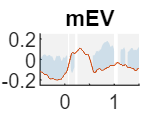

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


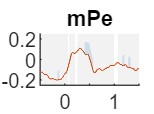

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


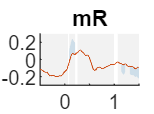

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


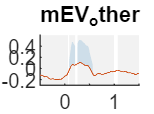

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


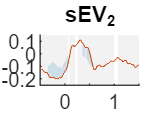

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


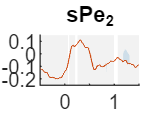

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


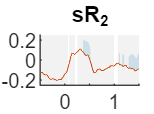

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


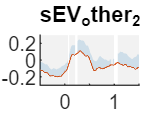

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


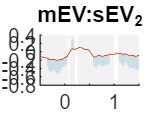

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


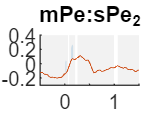

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            


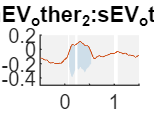

liner =   1×12 graphics array:

    GraphicsPlaceholder    Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon                Polygon            



statistics(2:end,tempstat{eachstat}.prob' > .05) = 0;

catbehv = behavior(:,[6:10]);
catbehv = catbehv - 1;

behaviorall = [behavior(:,[1:5]) catbehv behavior(:,[1:5]).*catbehv];

BehvTitlesall = {'mEV' 'mPe' 'mR' 'mEV_other',...
              'sEV_2' 'sPe_2' 'sR_2', 'sEV_other_2',...
              'mEV:sEV_2' 'mPe:sPe_2' 'mEV_other_2:sEV_other_2'};

ModelPredictors = behaviorall(:,ismember(BehvTitlesall,mdl.CoefficientNames(2:end)));

j = jet(length(table2array(mdl.Coefficients(:,4))));


ranges = {[0 20] [0 20] [0 20] [0 20] [0 1] [0 1] [0 1] [0 1] [0 20] [0 20] [0 20] };

uniquecluster = unique(tempstat{eachstat}.posclusterslabelmat);
uniquecluster = uniquecluster(uniquecluster ~= 0);

allfig = figure;

for coef = 2:length(table2array(mdl.Coefficients(:,4)))

fig(coef) = figure;
top =  statistics(1,:) + statistics(coef,:)*ranges{coef-1}(2);    
bot =  statistics(1,:) + statistics(coef,:)*ranges{coef-1}(1);

pgon = polyshape([time_rawfreq.time fliplr(time_rawfreq.time)],[top fliplr(bot)],'Simplify', false);
liner(coef) = plot(pgon);
hold on
liner(coef).EdgeAlpha = 0;
liner(coef).FaceAlpha = .15;
%fig(coef).FaceColor = j(coef,:)

plot(time_rawfreq.time,statistics(1,:));

lims = liner(coef).Parent.YLim;

for clus = 1:length(uniquecluster)
   tops = find(tempstat{eachstat}.posclusterslabelmat == uniquecluster(clus),1,'first');
   bots =  find(tempstat{eachstat}.posclusterslabelmat == uniquecluster(clus),1,'last');

   pgon2 = polyshape([time_rawfreq.time([tops bots]) fliplr(time_rawfreq.time([tops bots]))],[lims(1) lims(1) lims(2) lims(2)]);
   plot(pgon2,'FaceColor','black','FaceAlpha',.05,'EdgeAlpha',0,'HandleVisibility','off');
   
end
ylim([lims]);
xlim(minmax(time_rawfreq.time));
title([BehvTitlesall(coef-1)]);

set(0,'CurrentFigure',allfig);
liner(coef) = plot(pgon);
hold on
liner(coef).EdgeAlpha = 0;
liner(coef).FaceAlpha = .15;
liner(coef).FaceColor = j(coef,:)

end

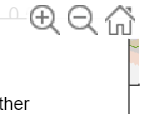


plot(time_rawfreq.time,statistics(1,:));

lims = liner(coef).Parent.YLim;

for clus = 1:length(uniquecluster)
   tops = find(tempstat{eachstat}.posclusterslabelmat == uniquecluster(clus),1,'first');
   bots =  find(tempstat{eachstat}.posclusterslabelmat == uniquecluster(clus),1,'last');

   pgon = polyshape([time_rawfreq.time([tops bots]) fliplr(time_rawfreq.time([tops bots]))],[lims(1) lims(1) lims(2) lims(2)]);
   plot(pgon,'FaceColor','black','FaceAlpha',.05,'EdgeAlpha',0,'HandleVisibility','off');
   
end
ylim([lims]);
xlim(minmax(time_rawfreq.time));


legend([mdl.CoefficientNames(2:end) mdl.CoefficientNames(1)]);


%  [sValue,condIdx,VarDecomp]  = collintest(behavior);
% 
% Deci.Analysis.Freq.Extra.Corr.Behavior = {'StableDoubleNegQ\mEV' 'StableDoubleNegQ\mPE' 'StableDoubleNegQ\mEV_next' 'StableDoubleNegQ\maEV' 'StableDoubleNegQ\mR' ...
%                                           'StableDoubleNegQ\sEV' 'StableDoubleNegQ\sPE' 'StableDoubleNegQ\sEV_next' 'StableDoubleNegQ\saEV' 'StableDoubleNegQ\sR'};

EV = figure;
mtop =  statistics(1,:) + statistics(2,:)*20 + statistics(6,:)*0 + statistics(10,:)*20*0;    
mbot =  statistics(1,:) + statistics(2,:)*20 + statistics(6,:)*1 + statistics(10,:)*20*1; 

plot(time_rawfreq.time,statistics(1,:),'Color','b');
hold on
plot(time_rawfreq.time,mtop,'Color','g','LineStyle','--');
plot(time_rawfreq.time,mbot,'Color','r','LineStyle','--');

lims = liner(coef).Parent.YLim;

for clus = 1:length(uniquecluster)
   tops = find(tempstat{eachstat}.posclusterslabelmat == uniquecluster(clus),1,'first');
   bots =  find(tempstat{eachstat}.posclusterslabelmat == uniquecluster(clus),1,'last');

   pgon2 = polyshape([time_rawfreq.time([tops bots]) fliplr(time_rawfreq.time([tops bots]))],[lims(1) lims(1) lims(2) lims(2)]);
   plot(pgon2,'FaceColor','black','FaceAlpha',.05,'EdgeAlpha',0,'HandleVisibility','off');
   
end






statenames = {'GN' 'g0' '0n' 'nN' 'GN' 'gn'};
for blk = 1:length(blkparam)

    dat = squeeze(nanmean(nanmean(blkparam{blk},2),3));

    figure;
    plot(dat')
    title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)

    figure;
    dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4));
    CleanBars(dat')
     title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)
end

